# TG3

#### Datos

x = [0 2 4 6 8 10 12 14 16 18 20 22 24];
y = [-50 -30 -10 20 50 80 100 90 70 40 10 -20 -40];

#### a) Interpolación Polinómica y Fenómeno de Runge (5 puntos):

p = lagrange(x,y)

p =     0.0000   -0.0000    0.0000   -0.0007    0.0172   -0.2682    2.8430  -20.3661   95.8955 -279.9755  451.0743 -289.3864  -50.0000


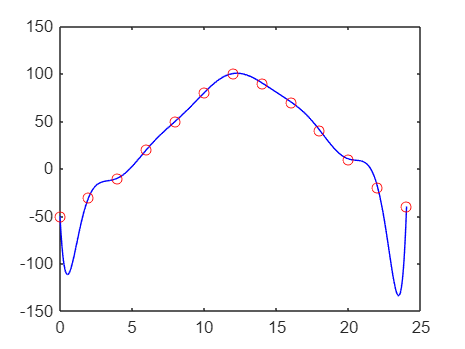


xx = 0:0.01:24;
yy = polyval(p,xx);

plot(xx,yy,'b',x,y,'ro');

En la grafica se puede observar oscilaciones significativas y abruptas en los extremos. Esto es una manifestación clara del fenómeno de Runge, causado por el uso de un polinomio de Lagrange de grado 11 para interpolar datos experimentales tomados en puntos equidistantes. Este problema surge porque los polinomios de grado elevado tienden a ser inestables en los extremos, especialmente cuando los puntos de interpolación están distribuidos equidistantemente (Burden et al., 2017).

Burden, R. L., Faires, J. D., & Burden, A. M. (2017). *Análisis numérico* (10ª ed.). Cengage Learning.

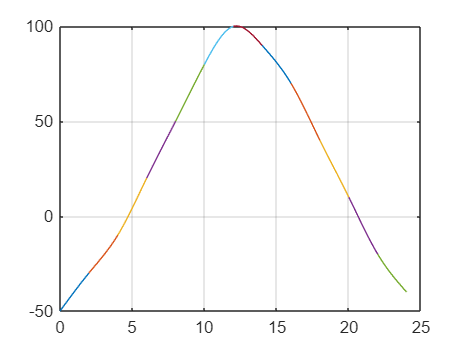

p =    -0.0902         0   10.3607  -50.0000
    0.4509   -0.5410    9.2786  -30.0000
   -0.4633    2.1642   12.5249  -10.0000
    0.1524   -0.6157   15.6218   20.0000
   -0.1463    0.2987   14.9878   50.0000
   -0.8171   -0.5792   14.4269   80.0000
    0.9149   -5.4821    2.3045  100.0000
   -0.3425    0.0074   -8.6449   90.0000
    0.4550   -2.0474  -12.7250   70.0000
   -0.2274    0.6823  -15.4552   40.0000



p = splinenatural(x,y)

#### b)

x = [0 2 4 6 8 10 12 14 16 18 20 22 24]';
y = [-50 -30 -10 20 50 80 100 90 70 40 10 -20 -40]';

M = [cos(pi/16 * x), sin(pi/16 * x), x, ones(size(x))];
A = M' * M

A = 1.0e+03 *

    0.0065    0.0012   -0.0735   -0.0020
    0.0012    0.0065   -0.0251    0.0020
   -0.0735   -0.0251    2.6000    0.1560
   -0.0020    0.0020    0.1560    0.0130


b = M' * y

b = 1.0e+03 *

   -0.3680
    0.2651
    4.3200
    0.3100


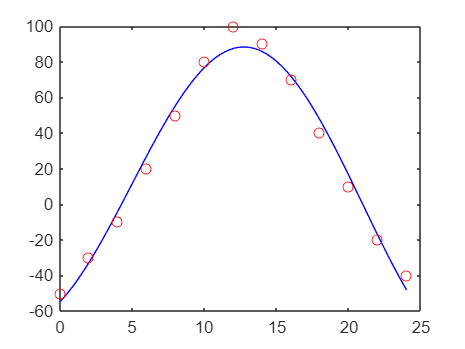

sol = linsolve(A, b);

A1 = sol(1);
A2 = sol(2);
D = sol(3);
E = sol(4);

f = @(t) A1 * cos(pi/16 * t) + A2 * sin(pi/16 * t) + D * t + E;

xx = 0:0.01: 24;
yy = f(xx);

plot(xx,yy,'b',x,y,'ro')

#### Funciones

function M=tabladif(x,y)
n=length(x);
M=zeros(n);
M(1:n,1)=y;
for k=1:n-1
deltax=x(k+1:n)-x(1:n-k);
deltay=diff(y)./deltax;
M(1:n-k,k+1)=deltay;
y=deltay;
end
M=[x M];
end

function p=polynewton(x,y)
M=tabladif(x,y)
n=length(x);
b=M(1,2:end);
p=b(1);
for k=2:n
p=[0 p]+b(k)*poly(x(1:k-1));
end
end

function p=lagrange(x,y)
n=length(x);
p=zeros(1,n);
for k=1:n
num=poly(x([1:k-1,k+1:n]));
den=polyval(num,x(k));
L=num/den;
p=p+y(k)*L;
end
end

function S=splinenatural(X,Y)
N=length(X)-1; H=diff(X); E=diff(Y)./H;
diagprinc=2*(H(1:N-1)+H(2:N)); diagsupinf=H(2:N-1);
g0=0; gn=0;
A=diag(diagprinc)+diag(diagsupinf,1)+diag(diagsupinf,-1);
b=6*diff(E'); g=A\b;
g=[g0 g' gn];
for i=1:N
S(i,1)=(g(i+1)-g(i))/(6*H(i));
S(i,2)=g(i)/2;
S(i,3)= E(i)-H(i)*(g(i+1)+2*g(i))/6;
S(i,4)=Y(i);
xx=linspace(X(i),X(i+1),100);
yy=S(i,1)*(xx-X(i)).^3+S(i,2)*(xx-X(i)).^2+S(i,3)*(xx-X(i))+S(i,4);
plot(xx,yy), hold on
end
grid on, hold off
end